clc;
clear;

k = 1; %valor do controlador (fica de 1 à 2, porém todos os valores dão estabilidade)
num = [0 0 1 1];
den = [1 3 0 0];

g1 = tf(num, den);
g2 = series(g1, k)

g2 =
 
     s + 1
  -----------
  s^3 + 3 s^2
 
Continuous-time transfer function.
Model Properties


g = feedback(g2, 1) %função da malha fechada

g =
 
         s + 1
  -------------------
  s^3 + 3 s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


stepinfo(g)

ans = struct with fields:
         RiseTime: 1.6672
    TransientTime: 32.7687
     SettlingTime: 32.7687
      SettlingMin: 0.6595
      SettlingMax: 1.6288
        Overshoot: 62.8781
       Undershoot: 0
             Peak: 1.6288
         PeakTime: 4.7907


var = dcgain(g1)

var = Inf

e = 1/(1+var) %valor do erro na resposta degrau

e = 0

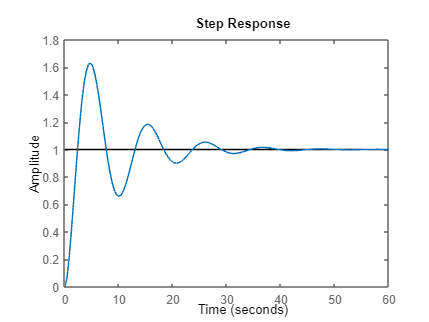


figure;
step(g)

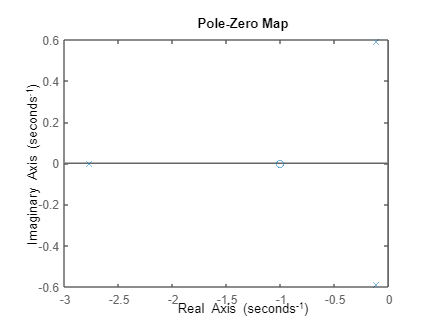

figure;
pzmap(g) %plano complexo

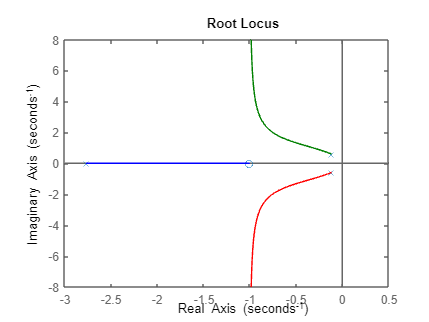

figure;
rlocus(g) %lugar das raízes